## Problem 2.94

A system has the state-variable description 

**A** = [1/2    -1/2

        1/3    0]

**b **= [    1

            2    ]

c = [1 -1]

D = [0]

(a) Use the MATLAB commands **lsim** and **impulse **to determine the first 30 values of the step and impulse responses of this system. 

(b) Define new states  z_1[n] = q_1[n] + q_2[n]         and 

                                    z_2[n] = 2q_1[n]. 

      Repeat Part (a) for the transformed system. 

Clarification from assignment module: 

            Typo Fix: z1[n] = q1[n] + q2[n] and z2[n] = 2q1[n]-q2[n]

## Part (a)

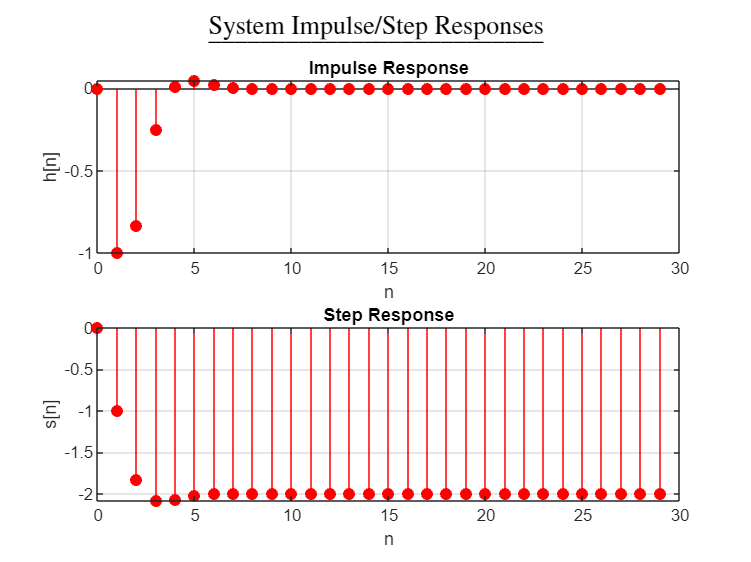

A = [1/2, -1/2; 1/3, 0];
b = [1; 2];
c = [1, -1];
D = 0;
n = 0:29; 
u = ones(1,30); 

subplot(2, 1, 1);   
sys = ss(A,b,c,D,-1);
h = impulse(sys,30);
stem(n, h(1:30),'filled','Color','r') % First 30 of impulse response
title('Impulse Response'); 
xlabel('n');
ylabel('h[n]');
grid on;

subplot(2, 1, 2);   
s = lsim(sys, u); % Step response
stem(n, s(1:30),'filled','Color','r') % First 30 of step response
title('Step Response'); 
xlabel('n');
ylabel('s[n]');
grid on;

sgtitle('\underline{System Impulse/Step Responses}', 'Interpreter', 'latex'); % Overall Title

## Part (b)

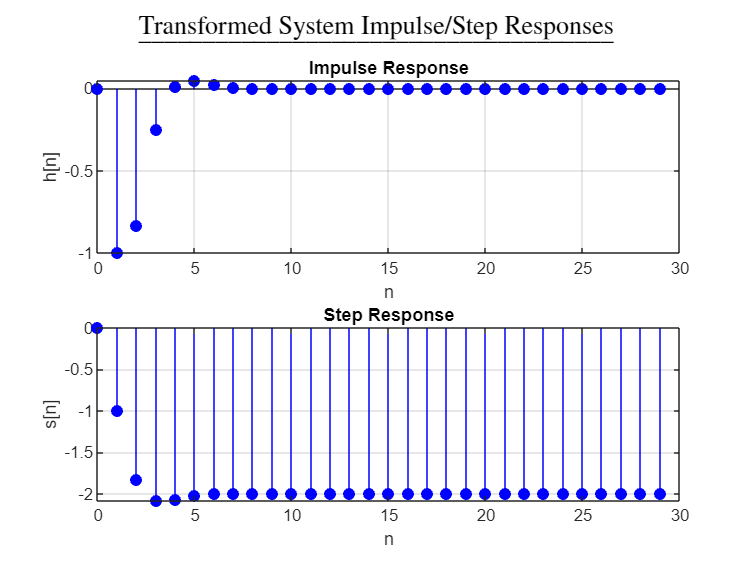

clf; % Clear current figure (so can run multiple subplots at once)
A = [1/2, -1/2; 1/3, 0];
b = [1; 2];
c = [1, -1];
D = 0;
T = [1 1; 2 -1]; % Transformation matrix
n = 0:29; 
u = ones(1,30); 

subplot(2, 1, 1);   
sys = ss(A,b,c,D,-1);
sysT = ss2ss(sys, T);

h = impulse(sysT,30);
stem(n, h(1:30),'filled','Color','b') % First 30 of impulse response
title('Impulse Response'); 
xlabel('n');
ylabel('h[n]');
grid on;

subplot(2, 1, 2);   
s = lsim(sysT, u); % Step response
stem(n, s(1:30),'filled','Color','b') % First 30 of step response
title('Step Response'); 
xlabel('n');
ylabel('s[n]');
grid on;

sgtitle('\underline{Transformed System Impulse/Step Responses}', 'Interpreter', 'latex'); % Overall Title